clear all, close all, clc

## **Survey on Workshop**

load('srvAl.mat','Al_S2_Q07_trs','Al_S2_Q08_efc')

trust = Al_S2_Q07_trs;
efct = Al_S2_Q08_efc;

Now, let's find the values with Likert5 function

[y1, y2] = likert5(trust, efct);

Let's plot trustworthiness

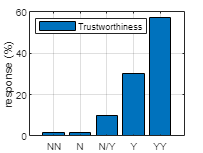

figure(1)
x = categorical({'NN','N','N/Y','Y','YY'});         % No /Yes
x = reordercats(x,{'NN','N','N/Y','Y','YY'});
y1;
y_p1 = y1/sum(y1) *100;

b = bar(x,y_p1); grid on 
ylabel('response (%)')
legend('Trustworthiness');
legend ('location','northwest')

And effectivity

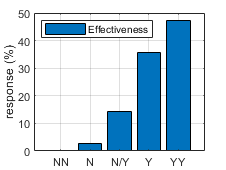

figure(2)
x = categorical({'NN','N','N/Y','Y','YY'});         % No /Yes
x = reordercats(x,{'NN','N','N/Y','Y','YY'});
y2;
y_p2 = y2/sum(y2) *100;

b = bar(x,y_p2); grid on
ylabel('response (%)')
legend('Effectiveness');
legend ('location','northwest')